# Full Sim Experiments

- variable step, auto, max=10, min=.01, tol=1e-4

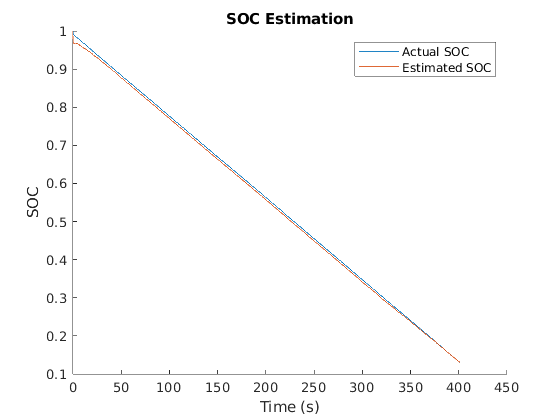

f1 = figure(1); clf;
hold on;
plot(soc.Time, soc.Data);
plot(soc_hat.Time, soc_hat.Data);
title("SOC Estimation");
legend(["Actual SOC", "Estimated SOC"]);
ylabel("SOC");
xlabel("Time (s)");
hold off;

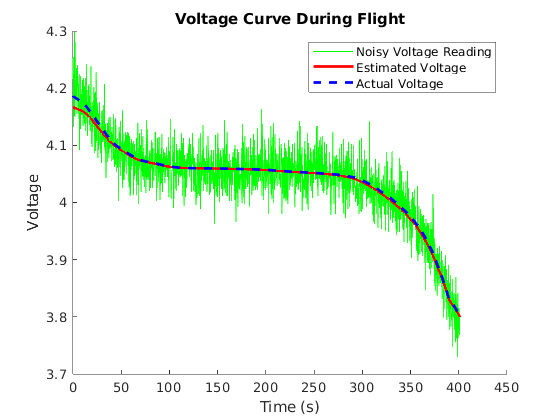

f2 = figure(2); clf;
hold on;
plot(noisy_v.Time, noisy_v.Data, 'g');
plot(v_batt_hat.Time, smoothdata(v_batt_hat.Data, 'movmean', 500), 'r', 'linewidth', 2);
plot(v_batt.Time, smoothdata(v_batt.Data, 'movmean', 500), 'b--', 'linewidth', 2);
hold off;
title("Voltage Curve During Flight");
xlabel("Time (s)");
ylabel("Voltage");
legend(["Noisy Voltage Reading", "Estimated Voltage", "Actual Voltage"]);

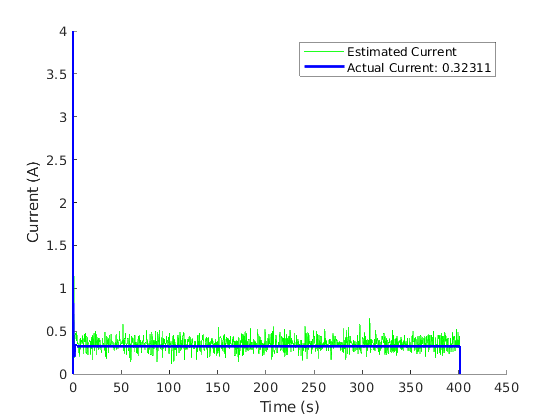

i_hatData = i_hat.Data(1,:);
f3 = figure(3); clf;
hold on;
plot(i_hat.Time, i_hatData, 'g');
plot(i_mot.Time, i_mot.Data, 'b', 'linewidth', 2);
hold off;
% title("Single Motor Current Draw");
xlabel("Time (s)");
ylabel("Current (A)");
legend(["Estimated Current", "Actual Current: " + num2str(i_mot.Data(1000))]);
ylim([0 4]);

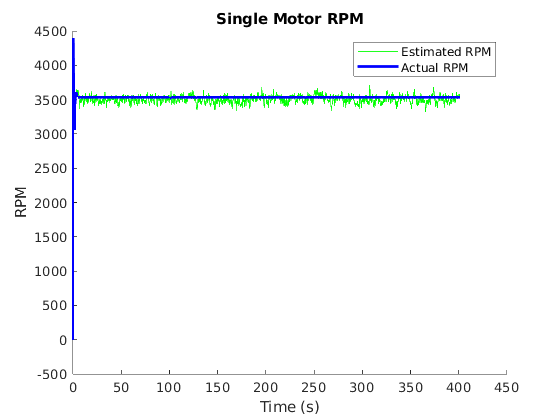

f4 = figure(4); clf;
hold on;
plot(rpm_hat.Time, rpm_hat.Data, 'g');
plot(rpm.Time, rpm.Data, 'b', 'linewidth', 2);
hold off;
xlabel("Time (s)");
ylabel("RPM");
title("Single Motor RPM");
legend(["Estimated RPM", "Actual RPM"]);

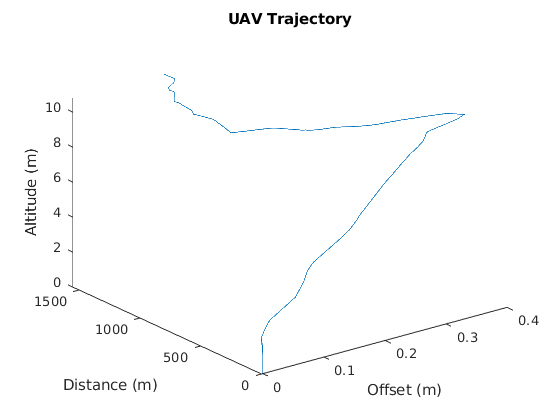

f5 = figure(5); clf;
plot3(pos(:,1), pos(:,2), pos(:,3));
%xlim([-1 1]);
xlabel("Offset (m)");
ylabel("Distance (m)");
zlabel("Altitude (m)");
title("UAV Trajectory");

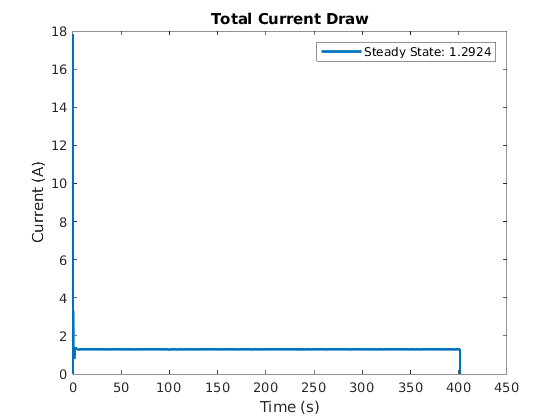

f6 = figure(6); clf;
plot(i_batt.Time, i_batt.Data, 'linewidth', 2);
title("Total Current Draw");
xlabel("Time (s)");
ylim([0 18]);
ylabel("Current (A)");
legend(["Steady State: " + num2str(i_batt.Data(1000))]);

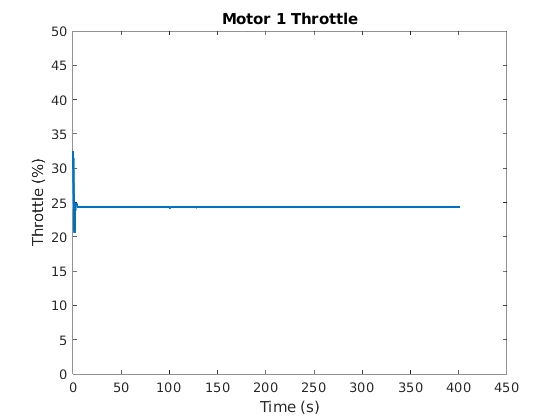

f7 = figure(7); clf;
plot(m1_throttle.Time, m1_throttle.Data, 'linewidth', 2);
title("Motor 1 Throttle");
xlabel("Time (s)");
ylabel("Throttle (%)");
ylim([0 50]);

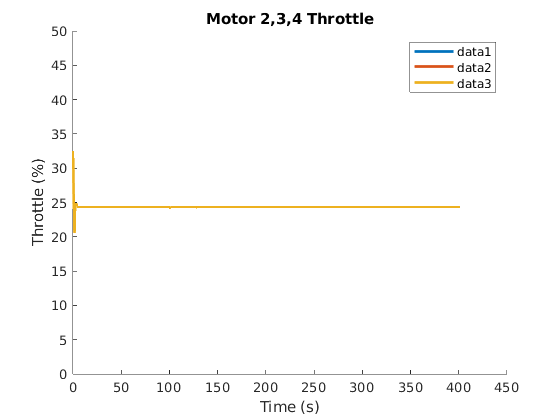

f8 = figure(8); clf;
hold on;
plot(m2_throttle.Time, m2_throttle.Data, 'linewidth', 2);
plot(m3_throttle.Time, m3_throttle.Data, 'linewidth', 2);
plot(m4_throttle.Time, m4_throttle.Data, 'linewidth', 2);
hold off;
title("Motor 2,3,4 Throttle");
xlabel("Time (s)");
ylabel("Throttle (%)");
ylim([0 50]);
legend()